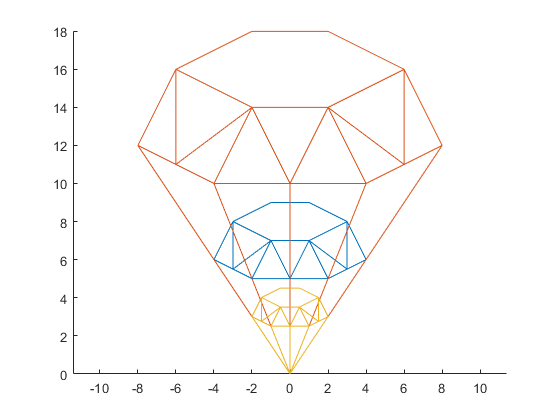

diamond = [0 4   3 1 2 0 0 -1 -2 0 -4 -3  -2 0 1 3   3 2 0 1 -1  -3 -3 -4 -3 -1 -3 -1 1 3 4;
           0 6 5.5 7 5 0 5  7  5 0  6 5.5  5 5 7 8 5.5 5 5 7 7  5.5  8  6  8  7  8  9 9 8 6];

a = 2;
A = [a 0; 0 a];
expansion = A*diamond;

b = 0.5;
B = [b 0; 0 b];
contraction = B*diamond;

axis equal; hold on
plotPoints(diamond); plotPoints(expansion); plotPoints(contraction);

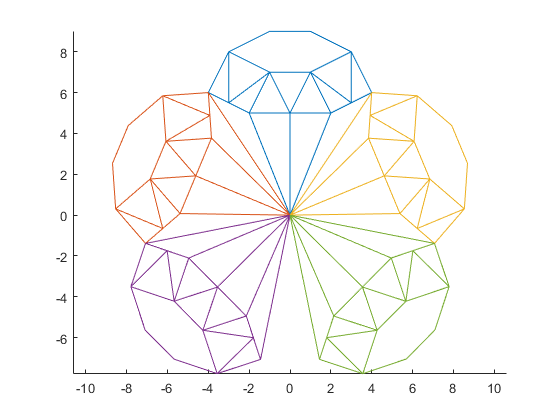

clf

v = 2*atan(4/6);
v2 = -2*atan(4/6);
v3 = 4*atan(4/6);
v4 = -4*atan(4/6);
R = [cos(v) -sin(v); sin(v) cos(v)];
rotation = R*diamond;
R2 = [cos(v2) -sin(v2); sin(v2) cos(v2)];
rotation2 = R2*diamond;
R3 = [cos(v3) -sin(v3); sin(v3) cos(v3)];
rotation3 = R3*diamond;
R4 = [cos(v4) -sin(v4); sin(v4) cos(v4)];
rotation4 = R4*diamond;

axis equal; hold on
plotPoints(diamond); plotPoints(rotation);plotPoints(rotation2);plotPoints(rotation3);plotPoints(rotation4);

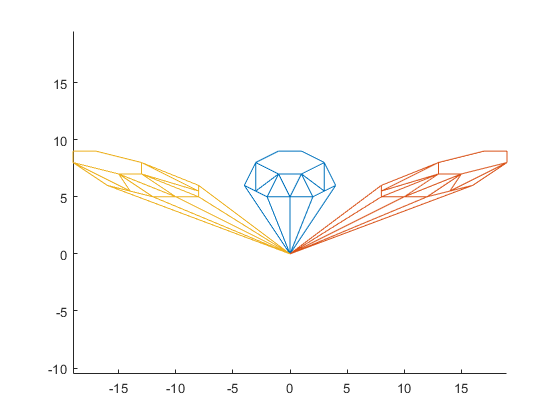


clf

c = 2;
C = [1 c; 0 1];
skuvning = C*diamond;

axis equal; hold on;
plotPoints(diamond); plotPoints(skuvning);

C2 = [1 -c; 0 1];
skuvning2 = C2*diamond;

plot(skuvning2(1,:),skuvning2(2,:))

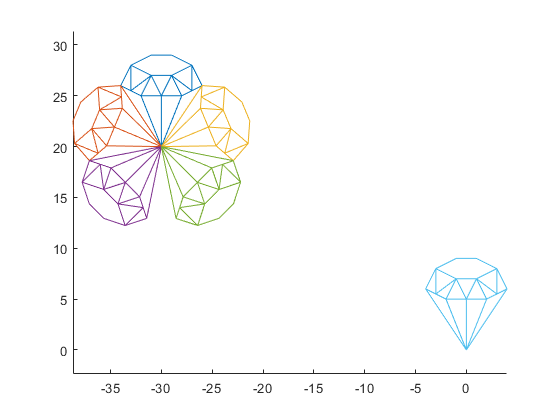




clf

diamond2 = [0 4   3 1 2 0 0 -1 -2 0 -4 -3  -2 0 1 3   3 2 0 1 -1  -3 -3 -4 -3 -1 -3 -1 1 3 4;
            0 6 5.5 7 5 0 5  7  5 0  6 5.5  5 5 7 8 5.5 5 5 7 7  5.5  8  6  8  7  8  9 9 8 6;
            1 1  1  1 1 1 1  1  1 1  1  1   1 1 1 1   1 1 1 1 1    1  1  1  1  1  1  1 1 1 1];

k = -30;
e = 20;
D = [1 0 k ; 0 1 e ; 0 0 1];
translation = D*diamond2;
%plot(translation(1,:),translation(2,:))

v = 2*atan(4/6);
v2 = -2*atan(4/6);
v3 = 4*atan(4/6);
v4 = -4*atan(4/6);
R1 = [cos(v) -sin(v) 0; sin(v) cos(v) 0 ; 0 0 1];
rotationv2 = D*R1*diamond2;
R2 = [cos(v2) -sin(v2) 0 ; sin(v2) cos(v2) 0 ; 0 0 1];
rotation2v2 = D*R2*diamond2;
R3 = [cos(v3) -sin(v3) 0 ; sin(v3) cos(v3) 0 ; 0 0 1];
rotation3v2 = D*R3*diamond2;
R4 = [cos(v4) -sin(v4) 0 ; sin(v4) cos(v4) 0 ; 0 0 1];
rotation4v2 = D*R4*diamond2;

axis equal; hold on
plotPoints(translation); plotPoints(rotationv2);plotPoints(rotation2v2);plotPoints(rotation3v2);plotPoints(rotation4v2); plotPoints(diamond2);% plotPoints(skuvningv2);;

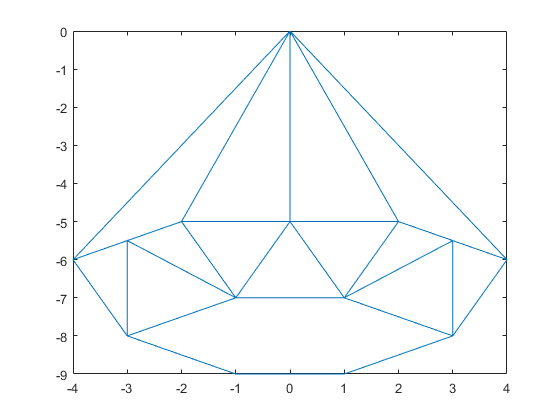


clf
v = pi;
R = [cos(v) -sin(v); sin(v) cos(v)];
rotation = R*diamond;
plotPoints(rotation);

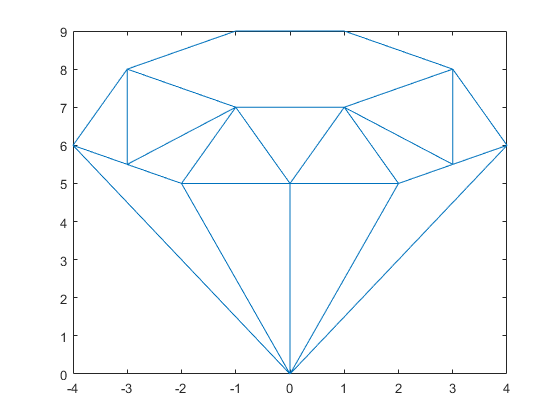

clf
c = 2;
C = [1 c; 0 1];
v = 2*atan(4/6);
R = [cos(v) -sin(v); sin(v) cos(v)];
rotation = R*diamond;
skuv= C*diamond;
plotPoints(diamond);

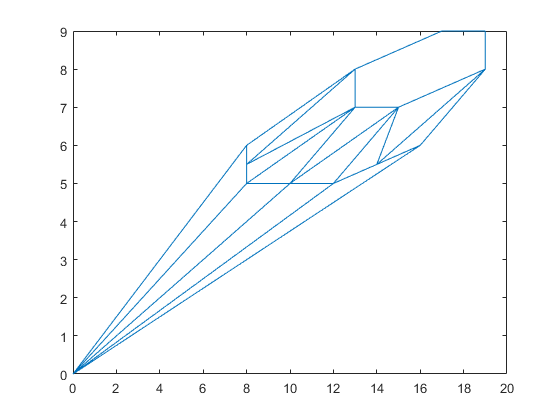

plotPoints(skuv);

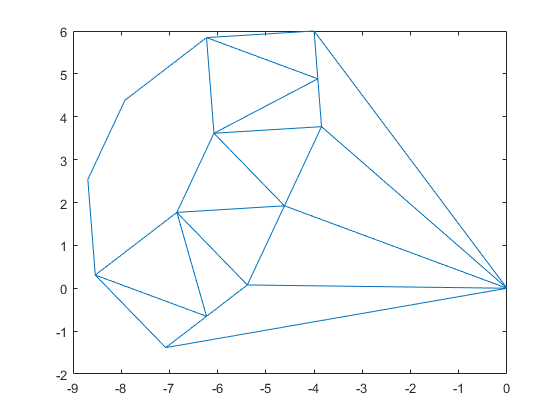

plotPoints(rotation);

RT = R*C*diamond

RT =          0    0.6154    0.3077   -0.6923    0.0000         0   -0.7692   -1.4615   -1.5385         0   -2.4615   -2.0000   -1.5385   -0.7692   -0.6923   -0.0769    0.3077    0.0000   -0.7692   -0.6923   -1.4615   -2.0000   -2.3846   -2.4615   -2.3846   -1.4615   -2.3846   -1.7692   -1.0000   -0.0769    0.6154
         0   17.0769   15.0385   16.5385   13.0000         0   11.1538   14.6923    9.3077         0    9.6923    9.5000    9.3077   11.1538   16.5385   20.6154   15.0385   13.0000   11.1538   16.5385   14.6923    9.5000   15.0769    9.6923   15.0769   14.6923   15.0769   19.1538   21.0000   20.6154   17.0769


TR = C*R*diamond

TR =          0    8.0000    5.8462    1.1538    3.6923         0   -0.7692   -3.3077   -5.2308         0   -9.8462   -7.5385   -5.2308   -0.7692    1.1538    5.4615    5.8462    3.6923   -0.7692    1.1538   -3.3077   -7.5385   -7.9231   -9.8462   -7.9231   -3.3077   -7.9231   -3.6154    0.8462    5.4615    8.0000
         0    6.0000    4.8846    3.6154    3.7692         0    1.9231    1.7692    0.0769         0   -1.3846   -0.6538    0.0769    1.9231    3.6154    5.8462    4.8846    3.7692    1.9231    3.6154    1.7692   -0.6538    0.3077   -1.3846    0.3077    1.7692    0.3077    2.5385    4.3846    5.8462    6.0000


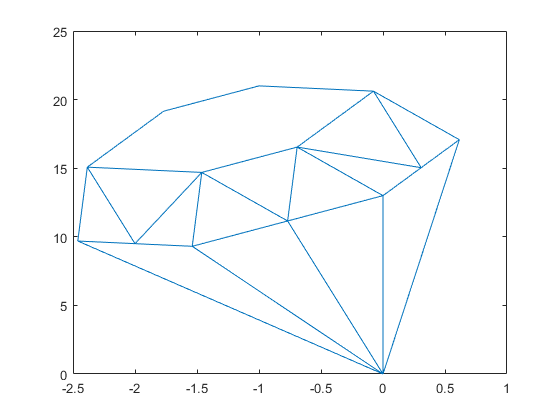

plotPoints(RT);

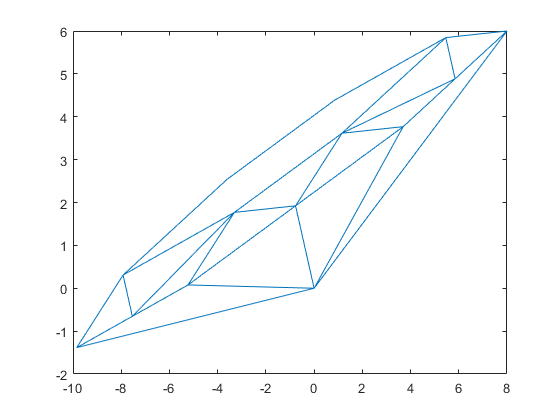

plotPoints(TR);